# Mapping in MATLAB

This tutorial will go through using the basic commands of the mapping toolbox in MATLAB. It is based on [this MathWorks tutorial.](https://www.mathworks.com/help/map/create-a-world-map.html)'

We start by loading in some shapefiles. A shapefile is the standard file format for geographical informaiton used in MATLAB, Python and GIS software.

land = readgeotable("landareas.shp");
rivers = readgeotable("worldrivers.shp");
cities = readgeotable("worldcities.shp");

MATLAB also has build-in data on coastlines, which can be loaded easily

load coastlines

The function newmap initialize new axes with some projection (note that newmap is only available after 2023a). The default in MATLAB is Equal Earth.

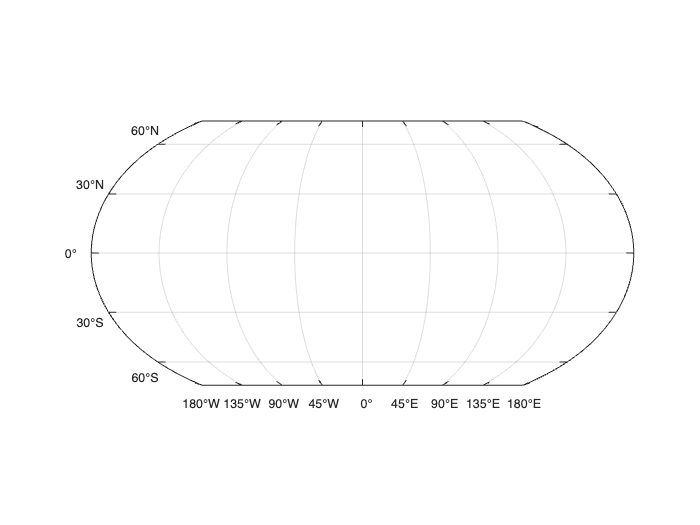

figure
newmap

geoplot plots line in geographic coordintes. It can also fill in lines (as below)

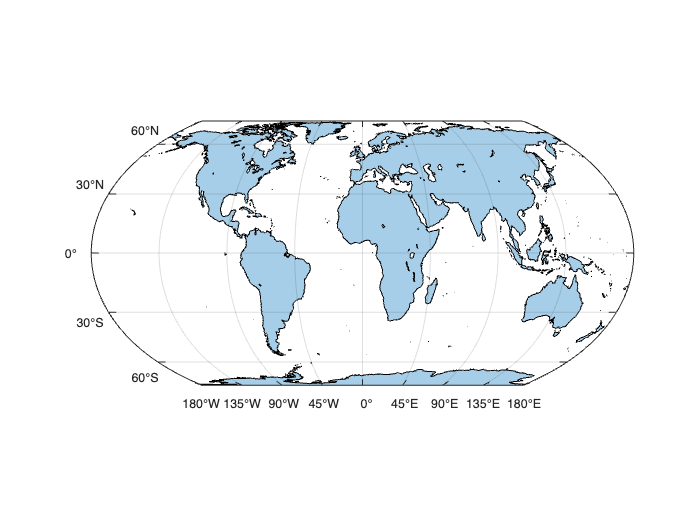

geoplot(land)

Other projections are also available using the projcrs function

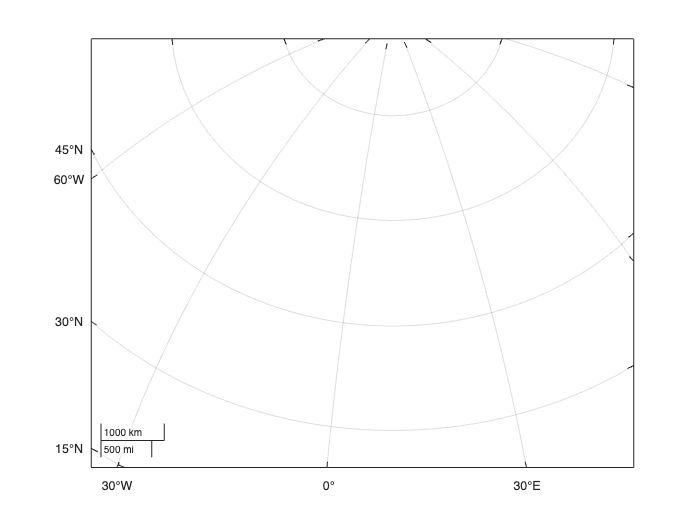

figure
p = projcrs(3035);
newmap(p)

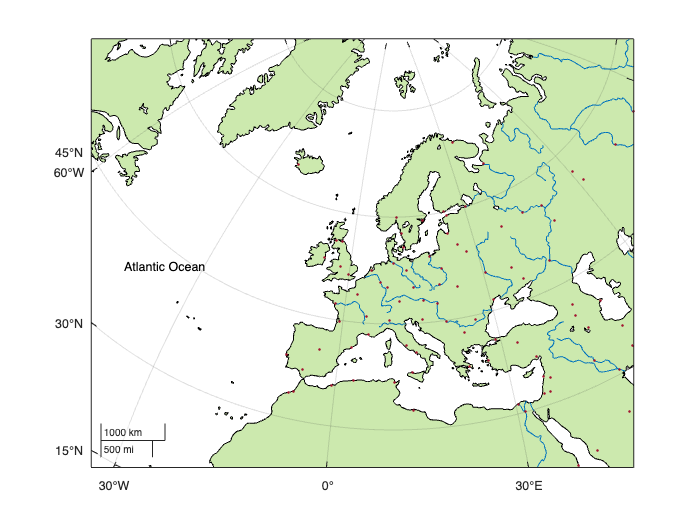

geoplot(land,FaceColor=[0.65 0.85 0.45]) %plot land in green this time
hold on
geoplot(rivers,Color=[0 0.4470 0.7410])  %plot rivers
geoplot(cities,MarkerEdgeColor=[0.6350 0.0780 0.1840]) %plot cities
text(39,-43,"Atlantic Ocean")

Making axesm-based plots ensures that the map projection properties are stored with the figure axes

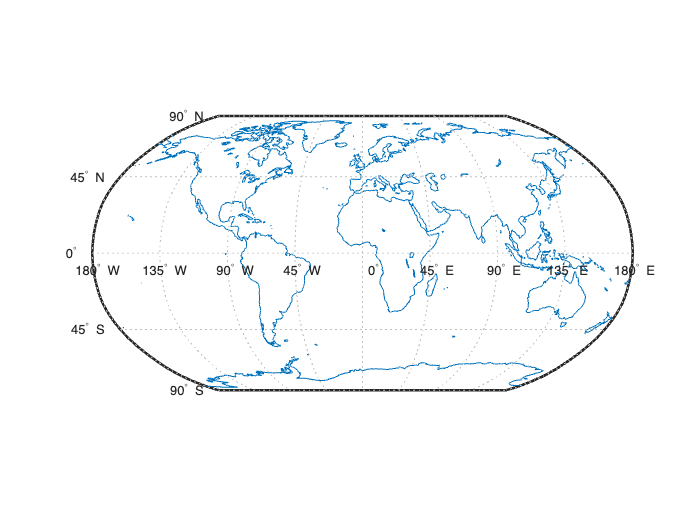

figure
worldmap world

load coastlines
plotm(coastlat,coastlon) %MATLAB has a whole setting of equivalent plotting functions with "m" added

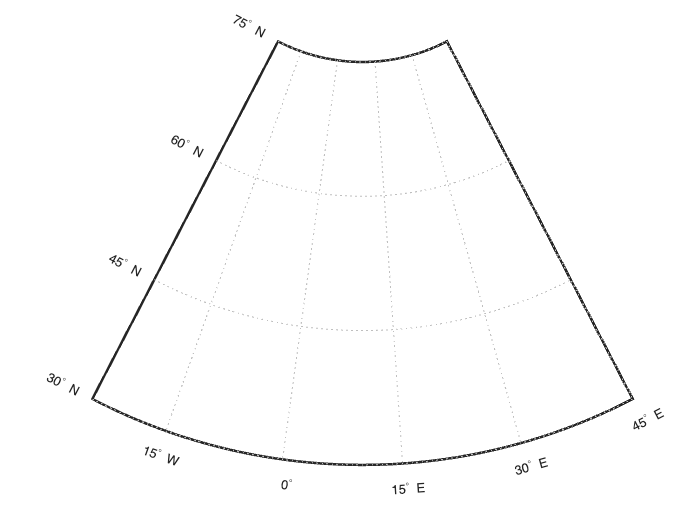

figure
worldmap europe


ax = gca;
getm(ax,"MapProjection") %query the map projection info

ans = 'eqdconic'

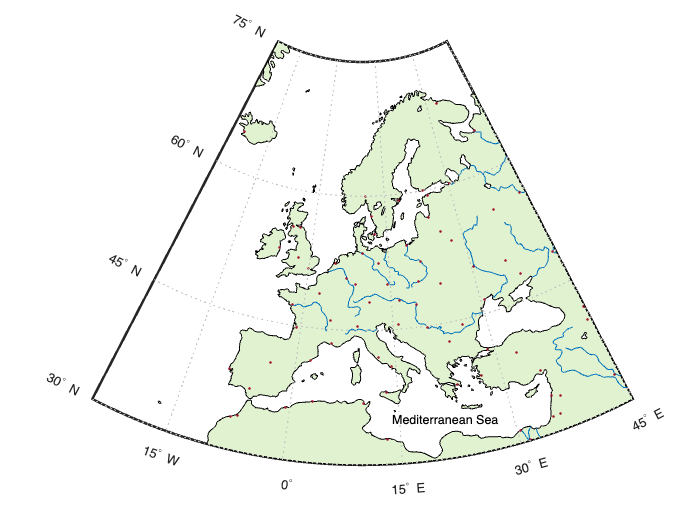

geoshow(land,"FaceColor",[0.88 0.95 0.81])
geoshow(rivers,"Color",[0 0.4470 0.7410])
geoshow(cities,"Marker",".","MarkerEdgeColor",[0.6350 0.0780 0.1840])
textm(35,14,"Mediterranean Sea")